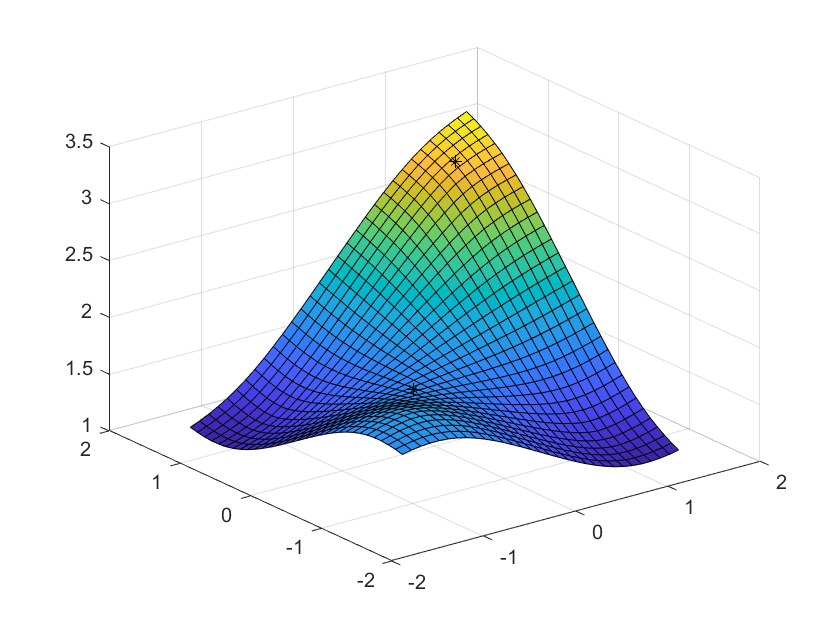

dataPoints = [1 1 3; 1 -1 1; -1 1 1; -1 -1 2];


F = ThinPlateSplines(dataPoints, 1);
x = -1.5:0.1:1.5;
y = x;
[X, Y] = meshgrid(x);
figure("Name", "Thin plate splines regression for different values of regularization parameters lambda")
surf(X, Y, F);
hold on;
plot3(dataPoints(:, 1), dataPoints(:, 2), dataPoints(:, 3), '*', "Color", 'black');
hold off;

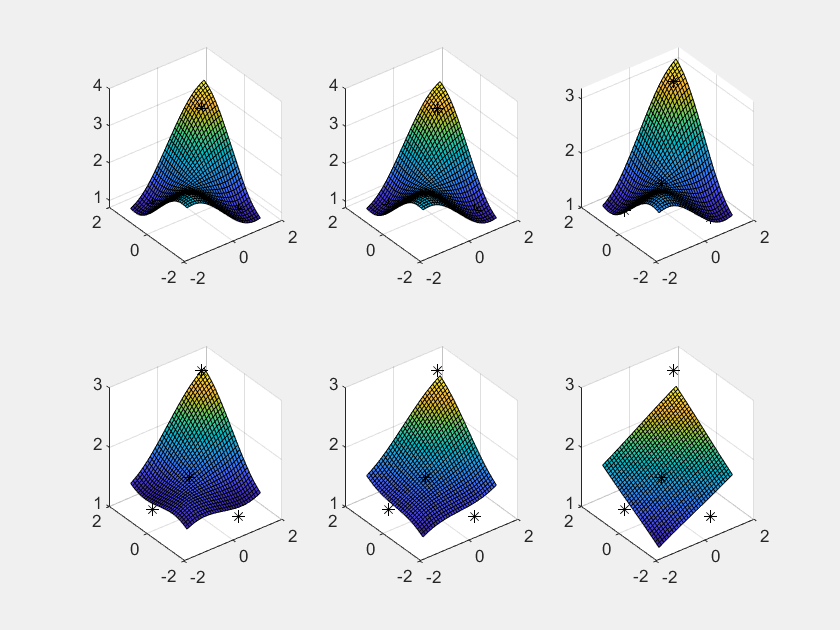

lambdas = [0, 0.1, 1, 5, 10, 100];
figure("Name", "Thin plate splines regression for different values of regularization parameters lambda")
set(gcf, 'Visible', 'on');
for i = 1:length(lambdas)
    F = ThinPlateSplines(dataPoints, lambdas(i));
    x = -1.5:0.1:1.5;
    y = x;
    [X, Y] = meshgrid(x);
    subplot(2, 3, i), title("lambda = ")
    surf(X, Y, F);
    hold on;
    plot3(dataPoints(:, 1), dataPoints(:, 2), dataPoints(:, 3), '*', "Color", 'black');
    hold off;
end